# RVC2: Chapter 10 - Light and Color

format compact
close all
clc
clear all

## 10.1  Spectral representation of light

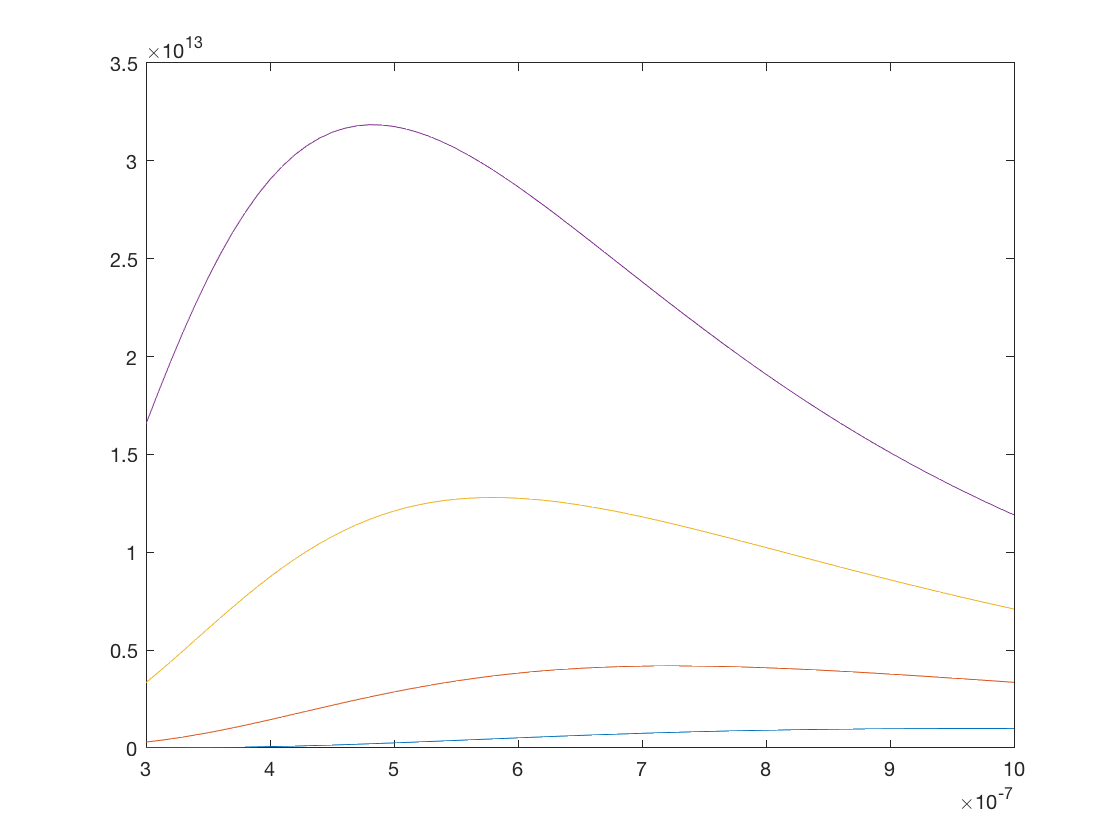

lambda = [300:10:1000]*1e-9;

for T=3000:1000:6000
    plot( lambda, blackbody(lambda, T)); hold all
end

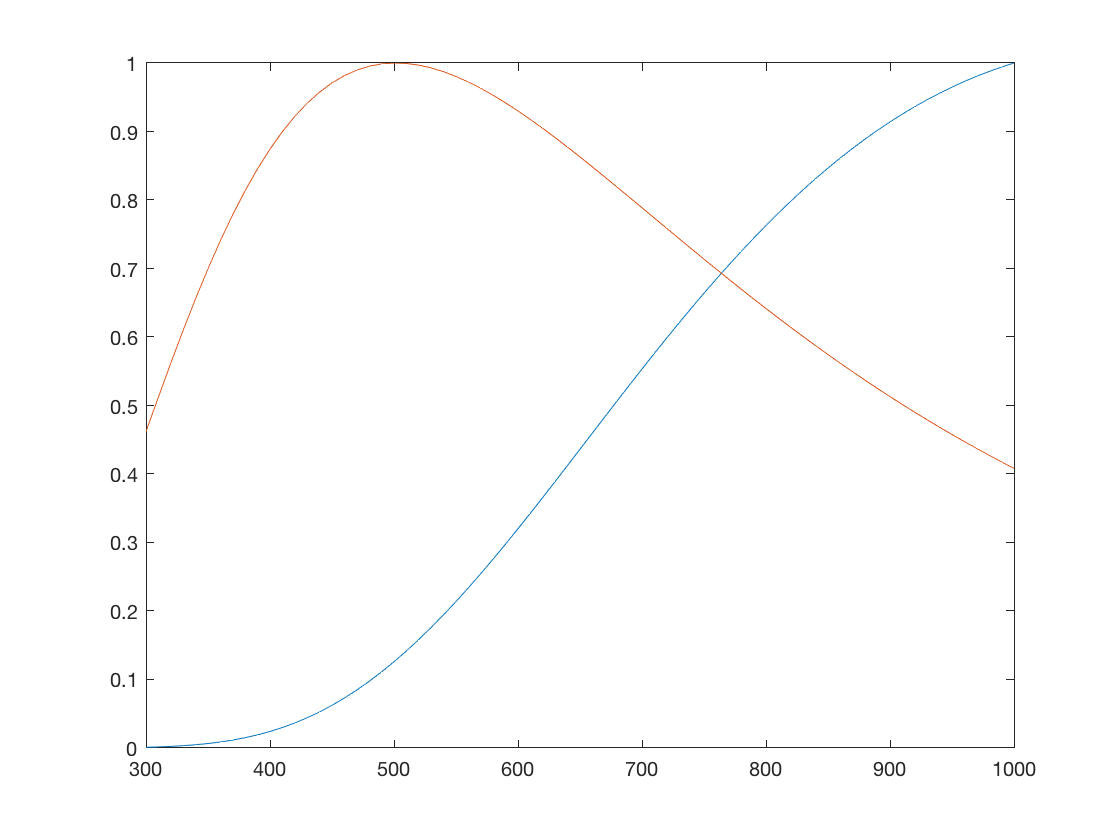


clf
lamp = blackbody(lambda, 2600);
sun = blackbody(lambda, 5778);
plot(lambda*1e9, [lamp/max(lamp) sun/max(sun)])

## 10.1.1  Absorption

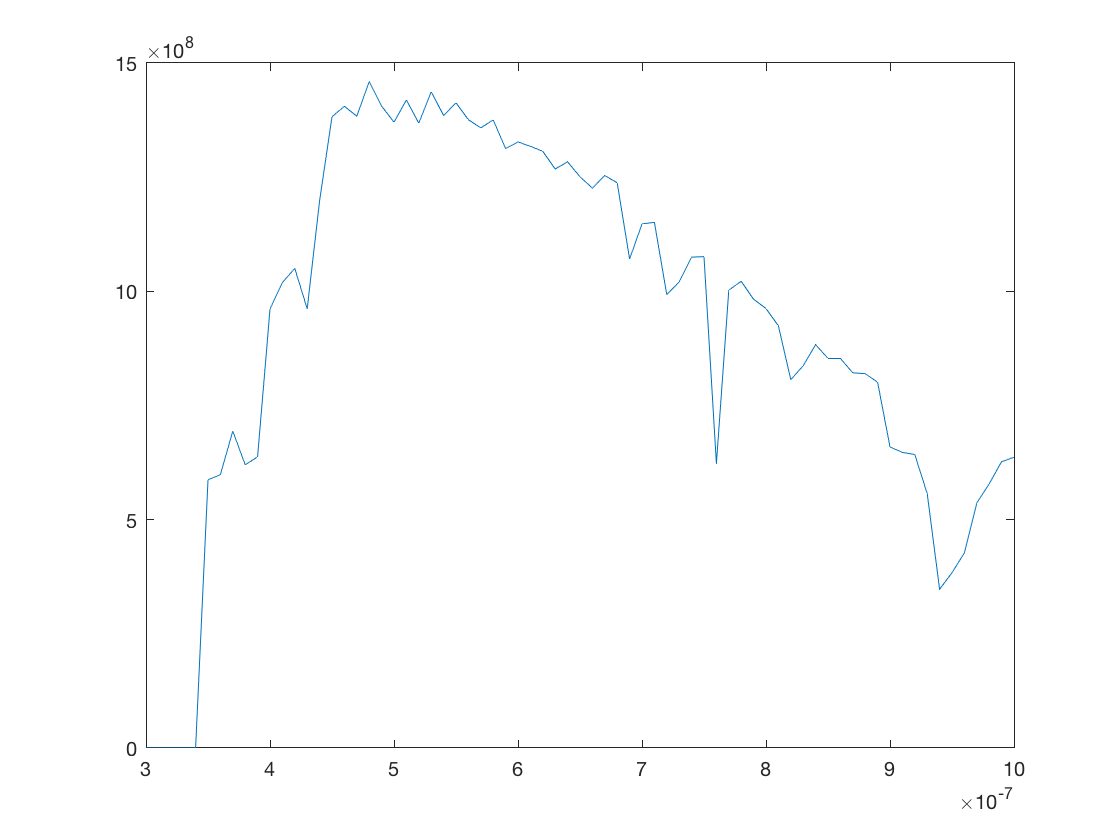

clf
sun_ground = loadspectrum(lambda, 'solar');
plot(lambda, sun_ground)

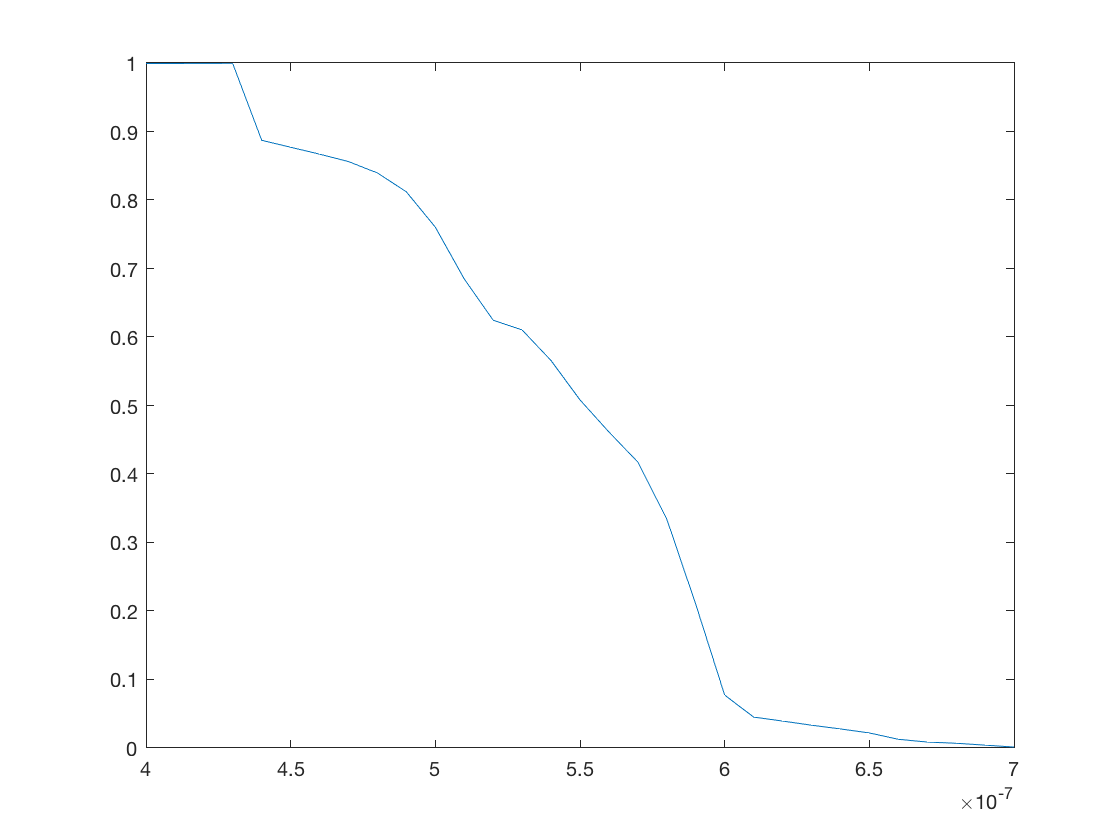


[A, lambda] = loadspectrum([400:10:700]*1e-9, 'water');
d = 5;
T = 10.^(-A*d);
plot(lambda, T);

## 10.1.2  Reflectance

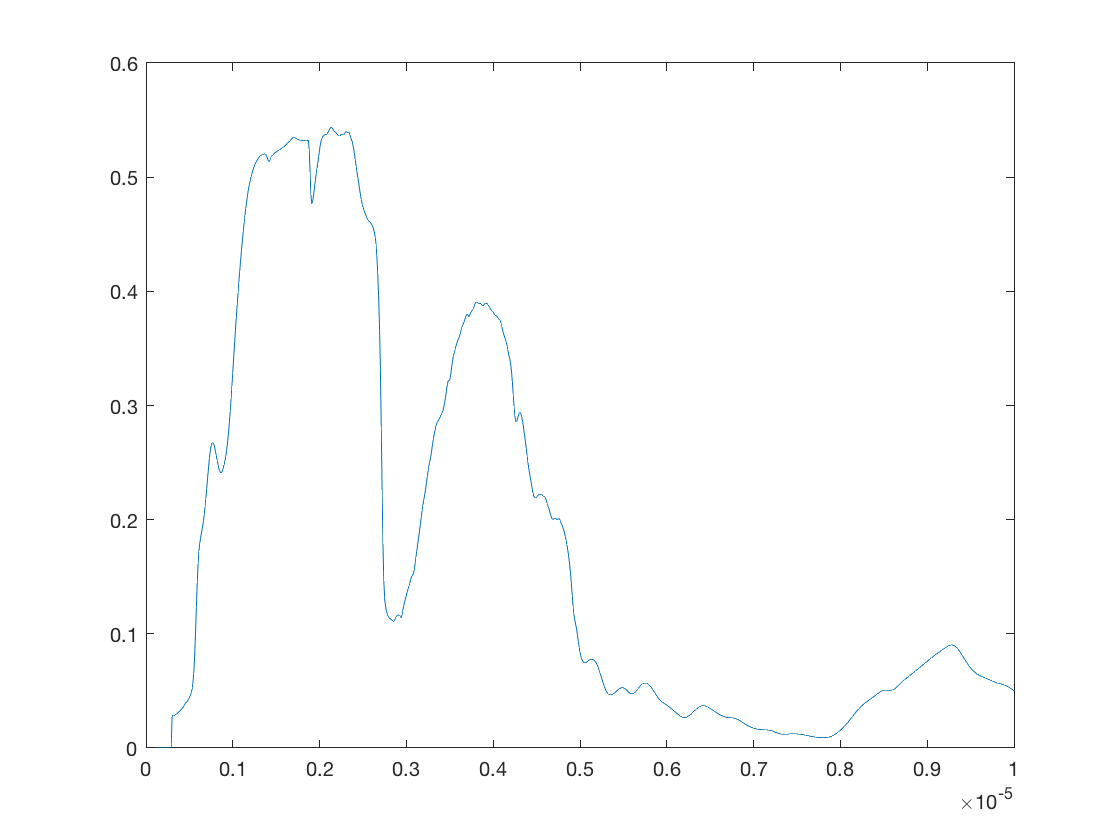

[R, lambda] = loadspectrum([100:10:10000]*1e-9, 'redbrick');
plot(lambda, R);

## 10.1.3  Luminance

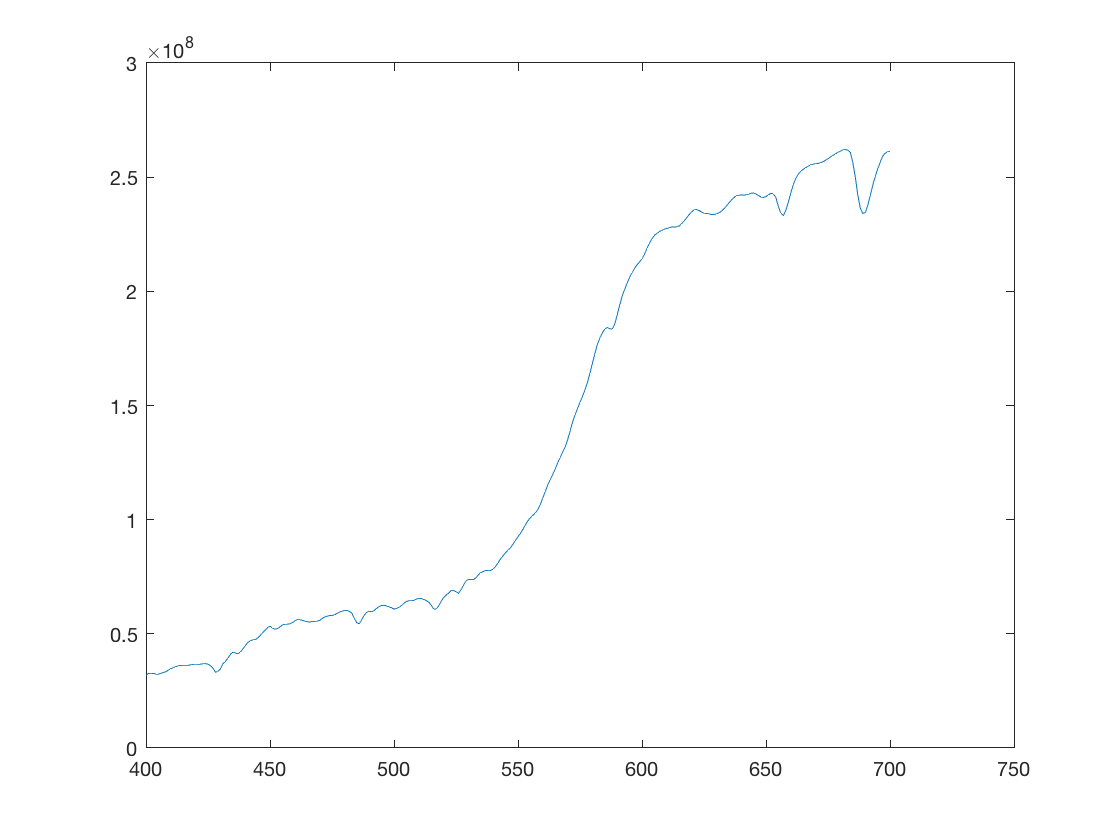

clf
lambda = [400:700]*1e-9;

E = loadspectrum(lambda, 'solar');

R = loadspectrum(lambda, 'redbrick');

L = E .* R;
plot(lambda*1e9, L);

## 10.2  Color

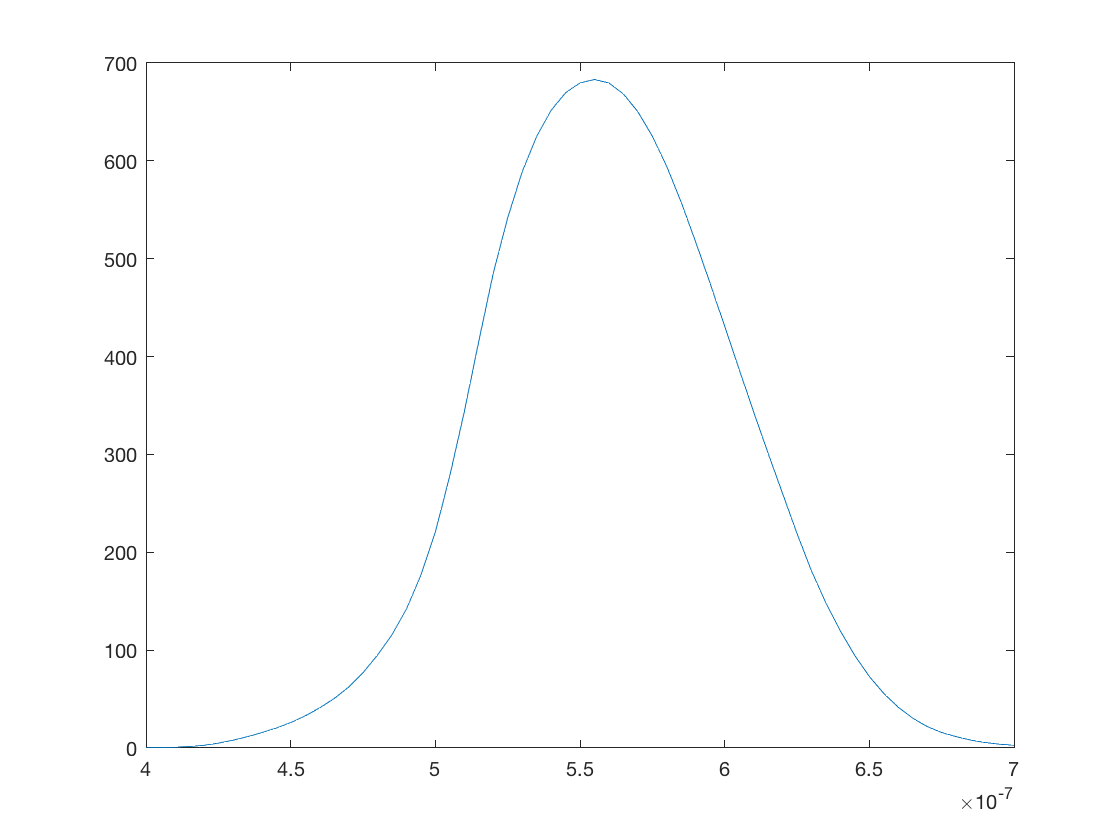

human = luminos(lambda);
plot(lambda,  human)


luminos(450e-9) / luminos(550e-9)

ans = 0.0382

## 10.2.1  The human eye

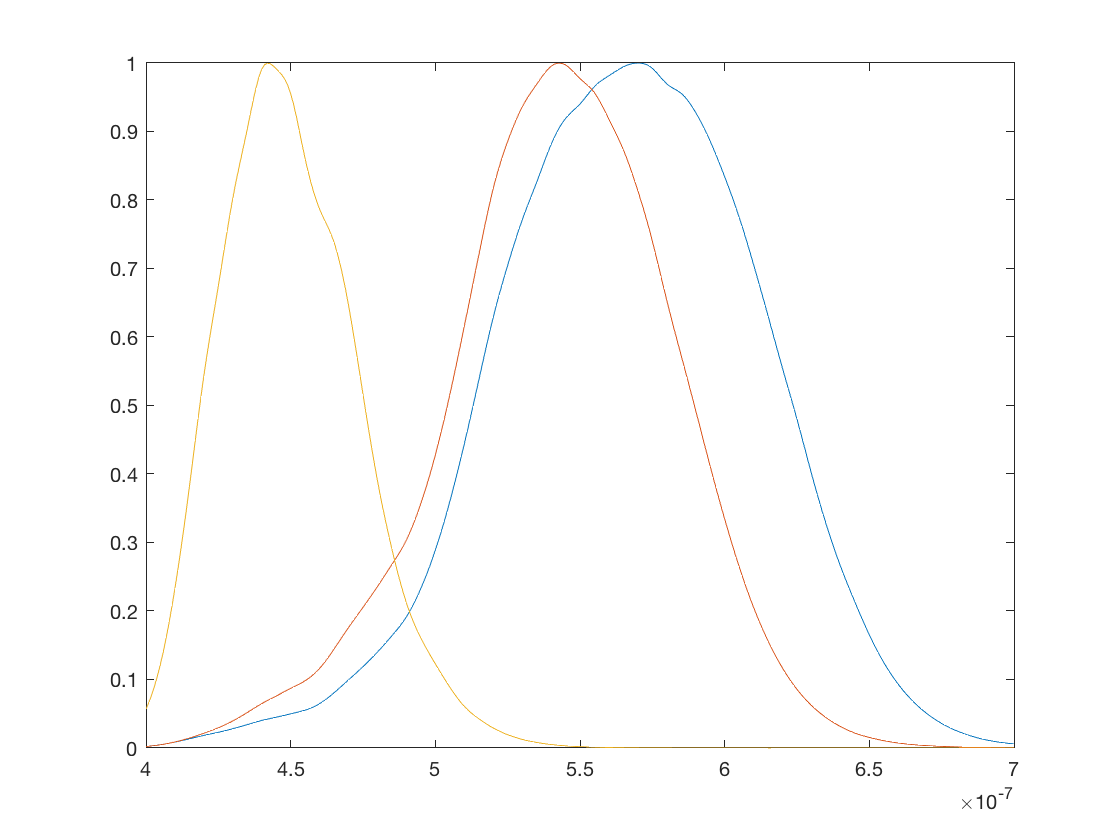

cones = loadspectrum(lambda, 'cones');
plot(lambda, cones)

## 10.2.2  Measuring color

sum( (L*ones(1,3)) .* cones * 1e-9)

ans =    16.3571   10.0665    2.8225


## 10.2.3  Reproducing colors

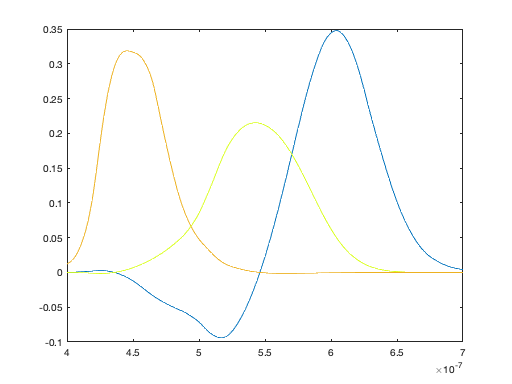

lambda = [400:700]*1e-9;
cmf = cmfrgb(lambda);
plot(lambda, cmf);


green = cmfrgb(500e-9)

green =    -0.0714    0.0854    0.0478



white = -min(green) * [1 1 1]

white =     0.0714    0.0714    0.0714



feasible_green = green + white

feasible_green =          0    0.1567    0.1191



RGB_brick = cmfrgb(lambda, L)

Undefined function or variable 'L'.

## 10.2.4  Chromaticity space

clf
[r,g] = lambda2rg( [400:700]*1e-9 );
plot(r, g)
rg_addticks

hold on
primaries = lambda2rg( cie_primaries() );
plot(primaries(:,1), primaries(:,2), 'o')

green_cc = lambda2rg(500e-9)

green_cc =    -1.1558    1.3823


plot2(green_cc, 's')

white_cc = tristim2cc([1 1 1])

white_cc =     0.3333    0.3333


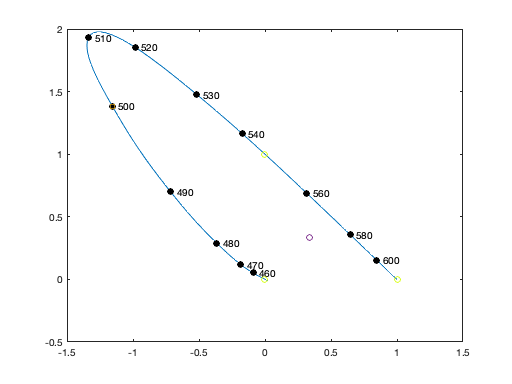

plot2(white_cc, 'o')

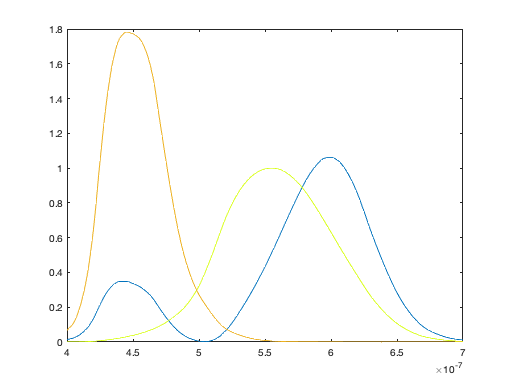


clf
cmf = cmfxyz(lambda);
plot(lambda, cmf);

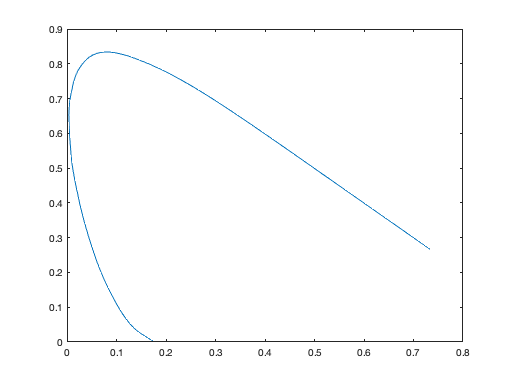


clf
[x,y] = lambda2xy(lambda);
plot(x, y);

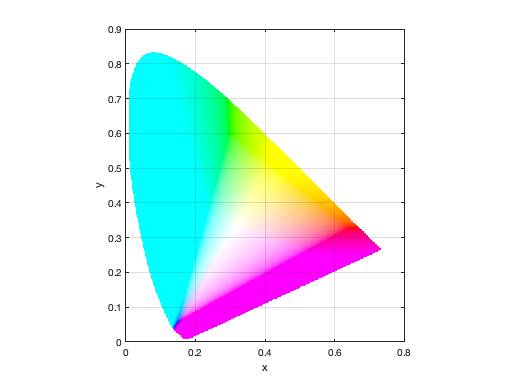


clf
showcolorspace('xy')


lambda2xy(550e-9)

ans =     0.3016    0.6923



lamp = blackbody(lambda, 2600);
lambda2xy(lambda, lamp)

ans =     0.4677    0.4127


## 10.2.5  Color names

colorname('?burnt')

loading rgb.txt


ans = 1×2 cell array
    {'burntsienna'}    {'burntumber'}


colorname('burntsienna')

ans =     0.5412    0.2118    0.0588



bs = colorname('burntsienna', 'xy')

bs =     0.5568    0.3783



colorname('chocolate', 'xy')

ans =     0.5318    0.3988



colorname([0.2 0.3 0.4])

ans = 'darkslateblue'

## 10.2.6  Other color and chromaticity spaces

colorspace('RGB->HSV', [1, 0, 0])

ans =      0     1     1


colorspace('RGB->HSV', [0, 1, 0])

ans =    120     1     1


colorspace('RGB->HSV', [0, 0, 1])

ans =    240     1     1



colorspace('RGB->HSV', [0, 0.5, 0])

ans =   120.0000    1.0000    0.5000



colorspace('RGB->HSV', [0.4, 0.4, 0.4])

ans =   240.0000         0    0.4000



colorspace('RGB->HSV', [0, 0.5, 0] + [0.4, 0.4, 0.4])

ans =   120.0000    0.5556    0.9000



flowers = iread('flowers4.png', 'double');
about flowers

flowers [double] : 426x640x3 (6.5 MB)



hsv = colorspace('RGB->HSV', flowers);
about hsv

hsv [double] : 426x640x3 (6.5 MB)


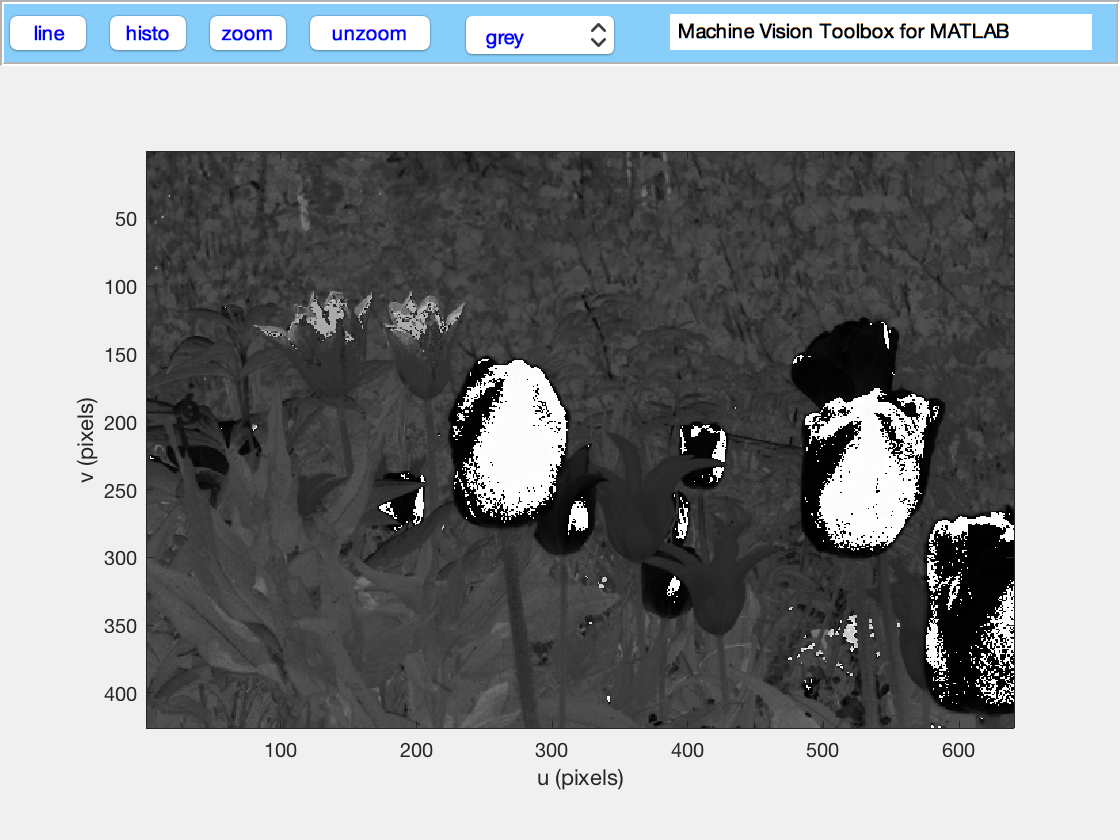


idisp( hsv(:,:,1) )

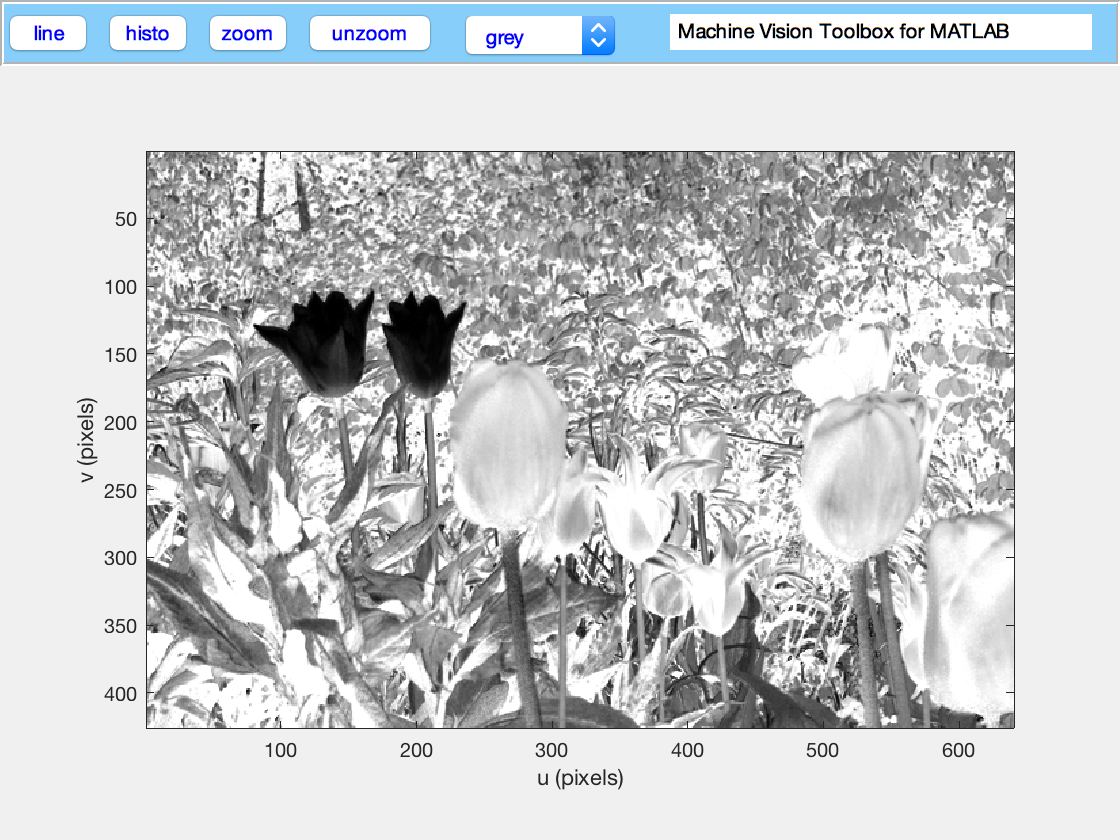

idisp( hsv(:,:,2) )

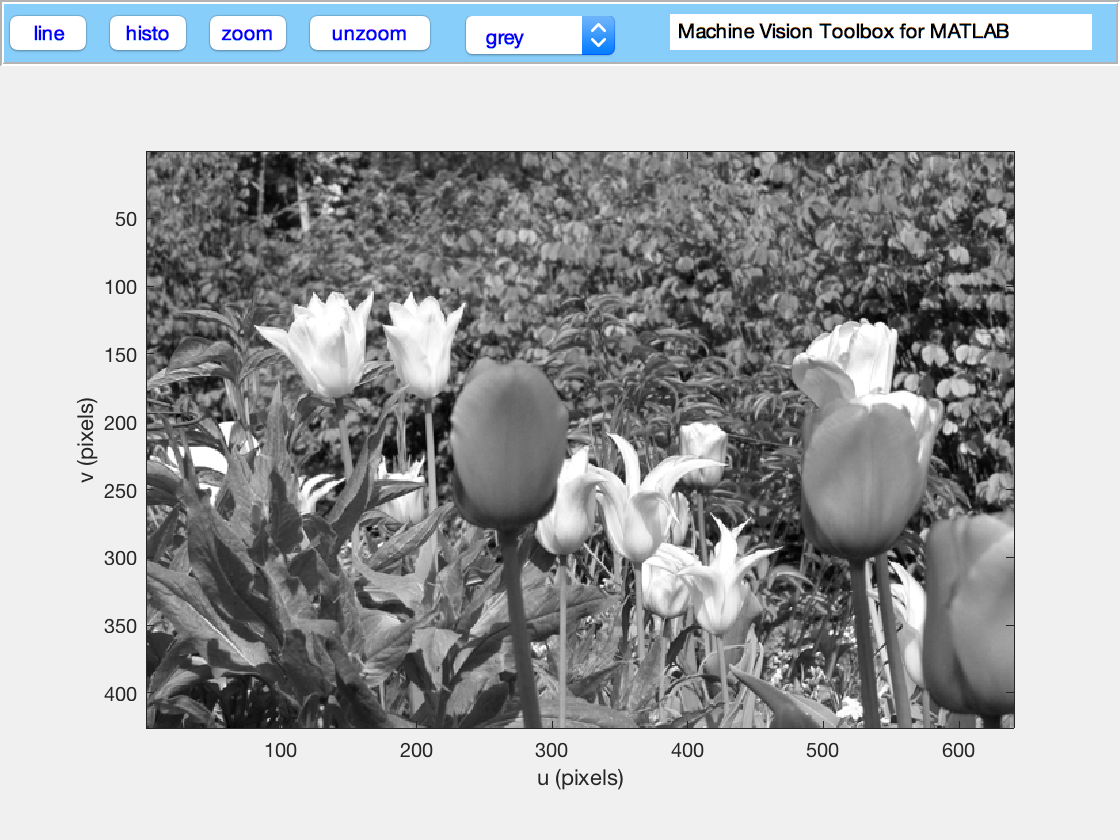

idisp( hsv(:,:,3) )


Lab = colorspace('RGB->Lab', flowers);
about Lab

Lab [double] : 426x640x3 (6.5 MB)


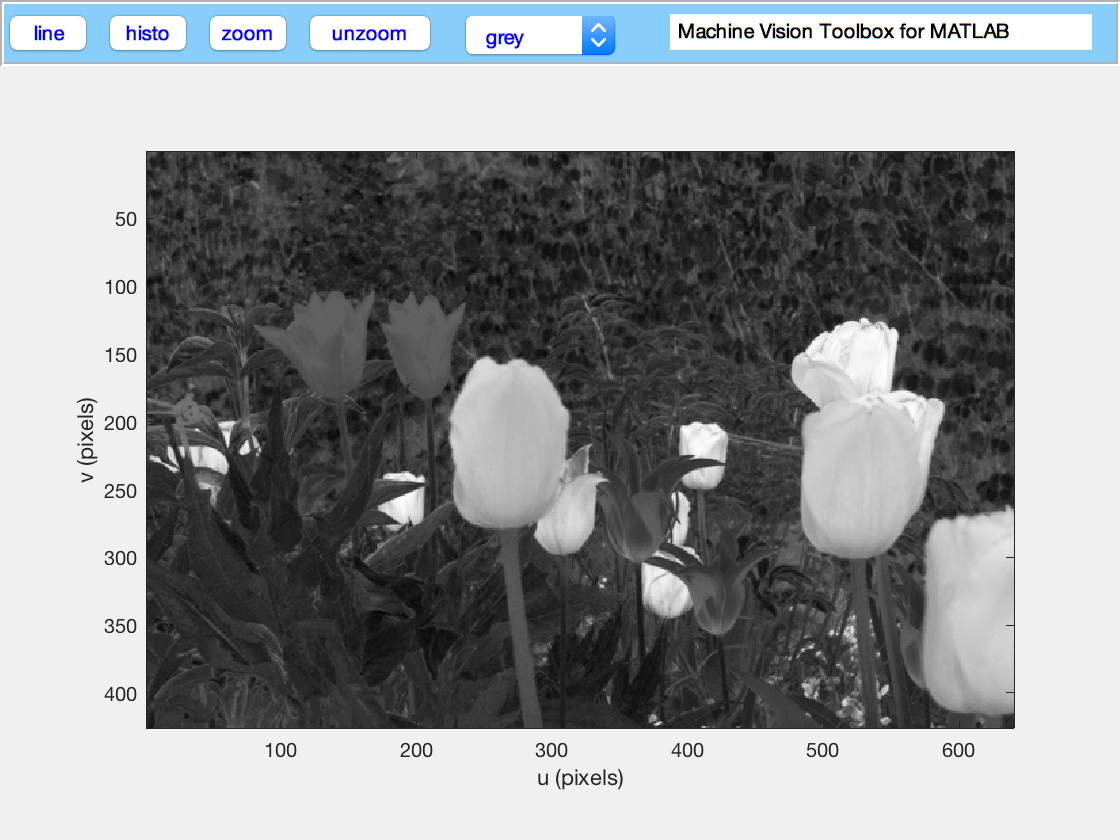


idisp(Lab(:,:,2))

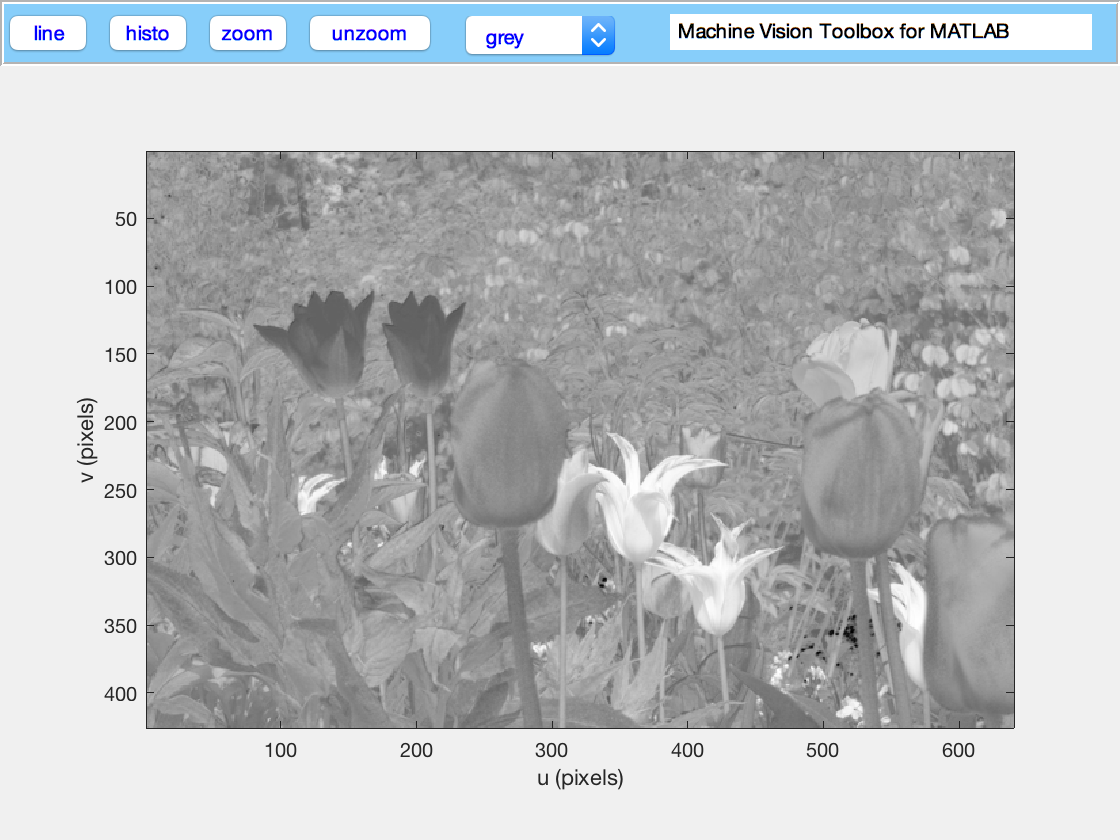

idisp(Lab(:,:,3))

## 10.2.7  Transforming between different primaries

C = [ 0.7347, 0.2653, 0; 0.2738, 0.7174, 0.0088; 0.1666, 0.0089, 0.8245]'

C =     0.7347    0.2738    0.1666
    0.2653    0.7174    0.0089
         0    0.0088    0.8245



J = inv(C) * [0.3127 0.3290 0.3582]' * (1/0.3290)

J =     0.5609
    1.1703
    1.3080


C * diag(J)

ans =     0.4121    0.3204    0.2179
    0.1488    0.8395    0.0116
         0    0.0103    1.0785



XYZ_brick = C * diag(J) * RGB_brick'

XYZ_brick =     0.0092
    0.0079
    0.0034



tristim2cc(XYZ_brick')

ans =     0.4483    0.3859


colorname(ans, 'xy')

ans = 'sandybrown'

## 10.2.8  What is white?

d65 = blackbody(lambda, 6500);
lambda2xy(lambda, d65)

ans =     0.3136    0.3243



ee = ones(size(lambda));

lambda2xy(lambda, ee)

ans =     0.3334    0.3340


## 10.3.2  Color constancy

lambda = [400:10:700]*1e-9;
R = loadspectrum(lambda, 'redbrick');

sun = loadspectrum(lambda, 'solar');

lamp = blackbody(lambda, 2600);

xy_sun = lambda2xy(lambda, sun .* R)

xy_sun =     0.4760    0.3784


xy_lamp = lambda2xy(lambda, lamp .* R)

xy_lamp =     0.5724    0.3877


## 10.3.4  Color change due to absorption

[R,lambda] = loadspectrum([400:700]*1e-9, 'redbrick.dat');

sun = loadspectrum(lambda, 'solar.dat');

A = loadspectrum(lambda, 'water.dat');

d = 2

d = 2


T = 10 .^ (-d*A);

L = sun  .* R .* T;

xy_water = lambda2xy(lambda, L)

xy_water =     0.3738    0.3814


## 10.3.6  Gamma

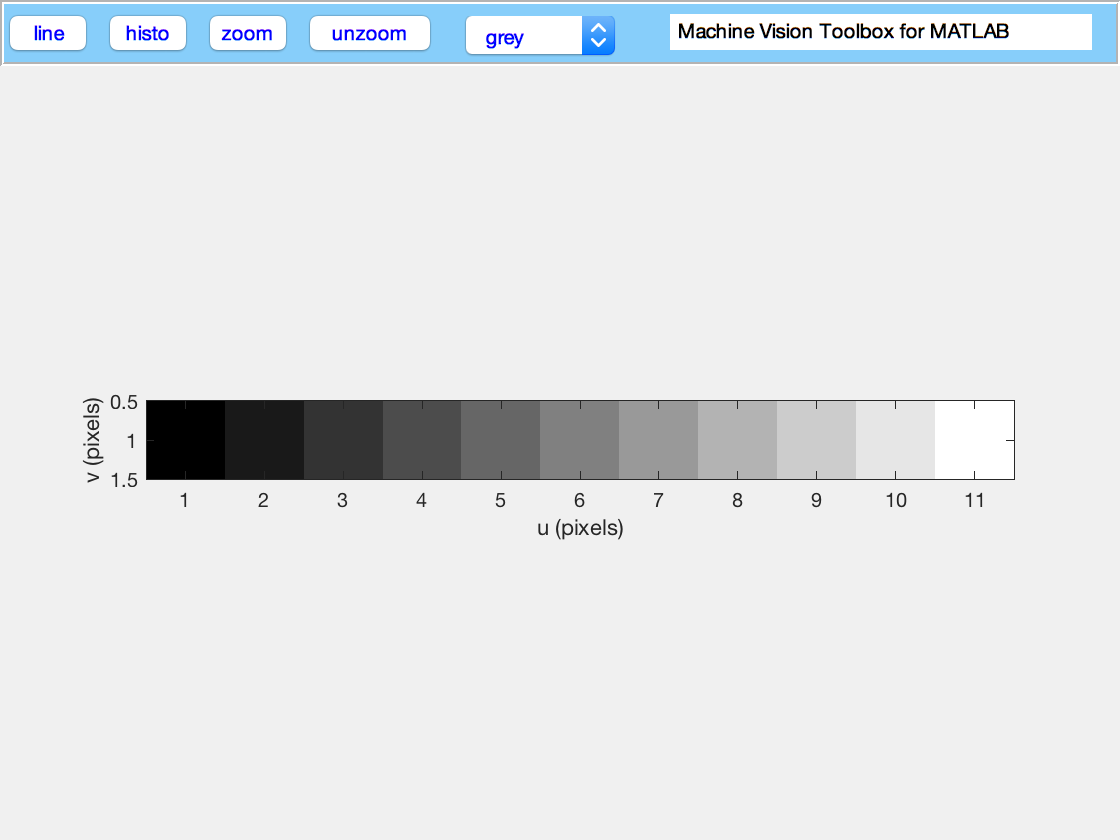

wedge = [0:0.1:1];
idisp(wedge)

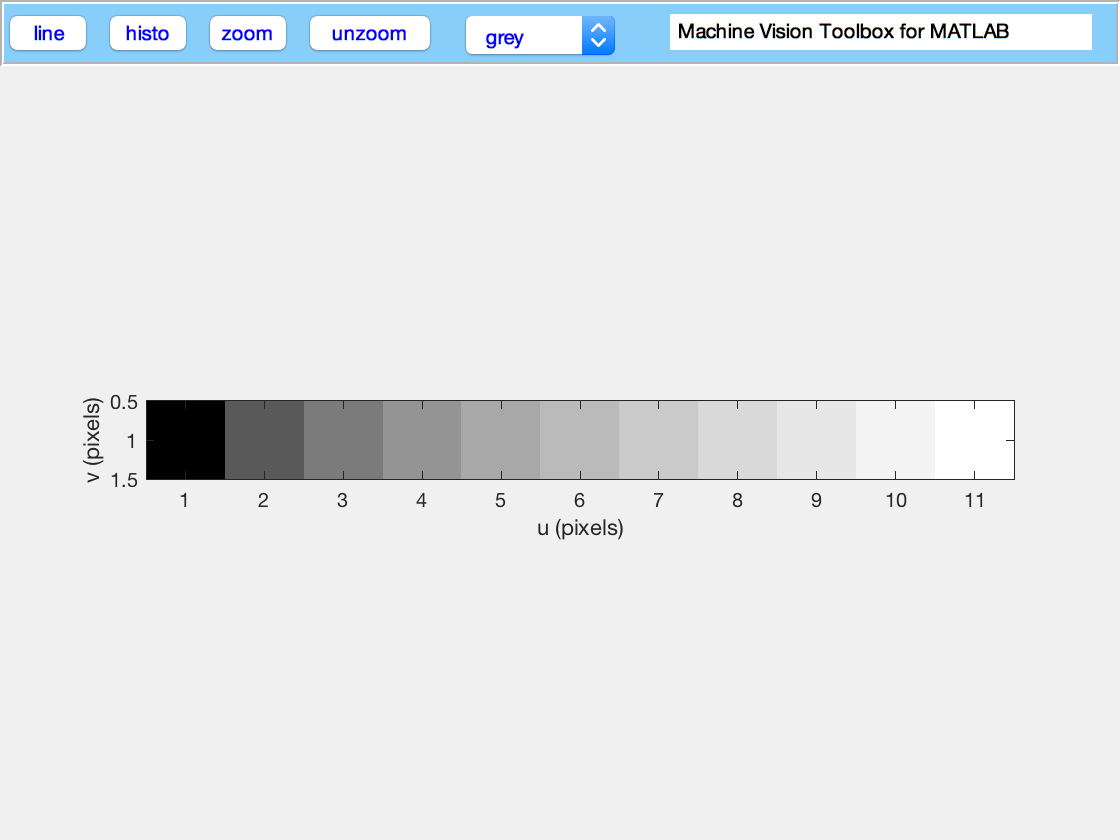


idisp( wedge .^ (1/2.2) )

## 10.4.1  Comparing color spaces

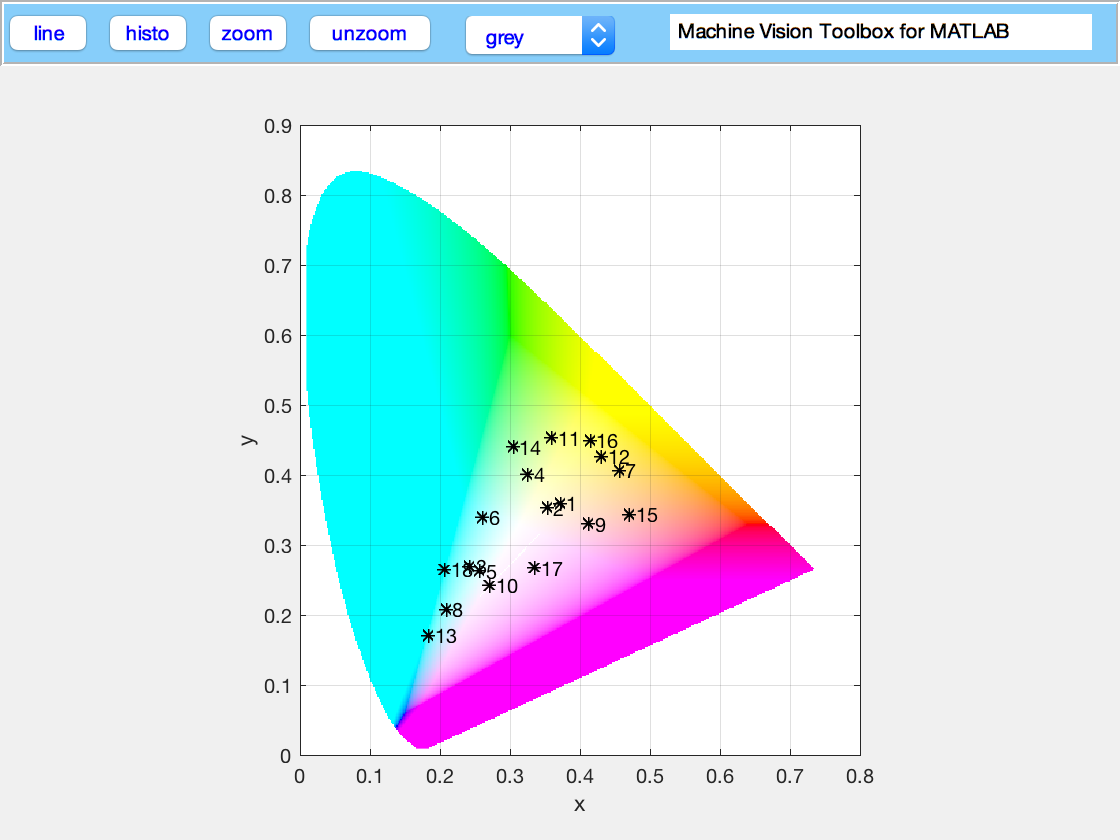

lambda = [400:5:700]*1e-9;
macbeth = loadspectrum(lambda, 'macbeth');

d65 = loadspectrum(lambda, 'D65') * 3e9;

clear XYZ Lab

for i=1:18
    L = macbeth(:,i) .* d65;
    tristim = max( cmfrgb(lambda, L), 0);
    RGB = igamm(tristim, 0.45);
    
    XYZ(i,:) = colorspace('RGB->XYZ', RGB);
    Lab(i,:) = colorspace('RGB->Lab', RGB);
end

xy = XYZ(:,1:2) ./ (sum(XYZ,2)*[1 1]);
ab = Lab(:,2:3);

showcolorspace('xy', xy');

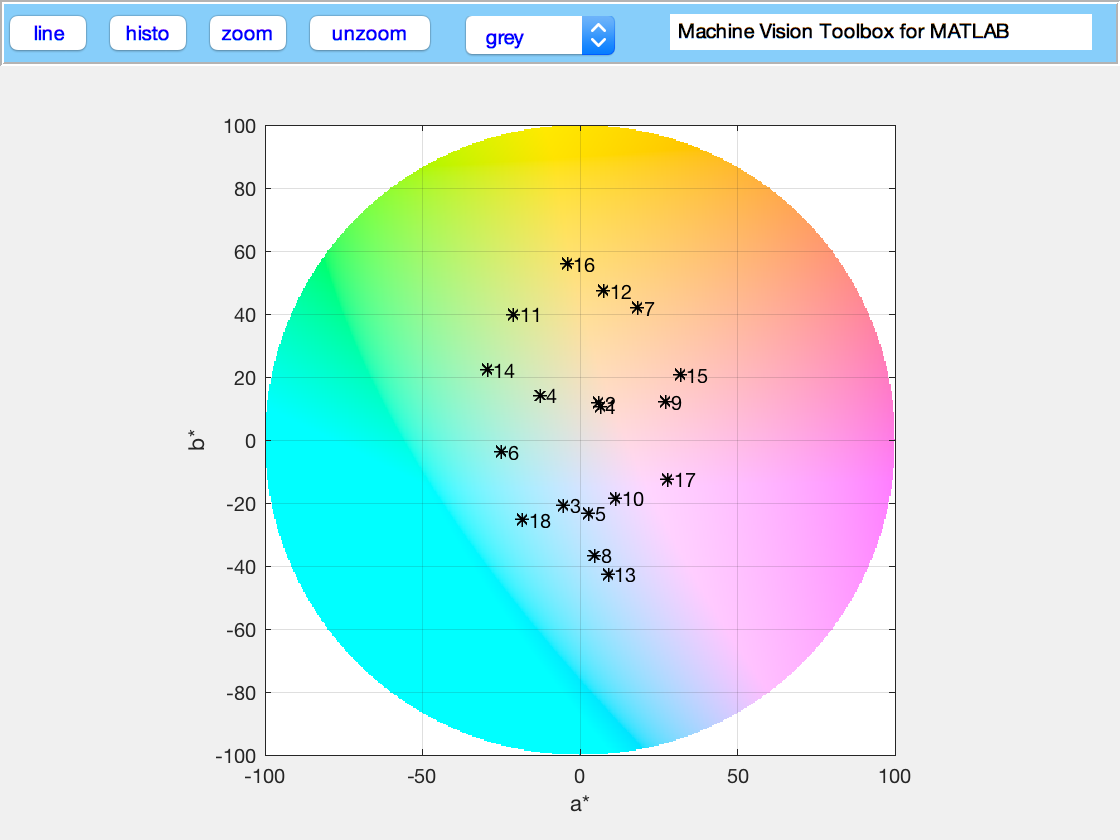

showcolorspace('Lab', ab');

## 10.4.2  Shadow removal

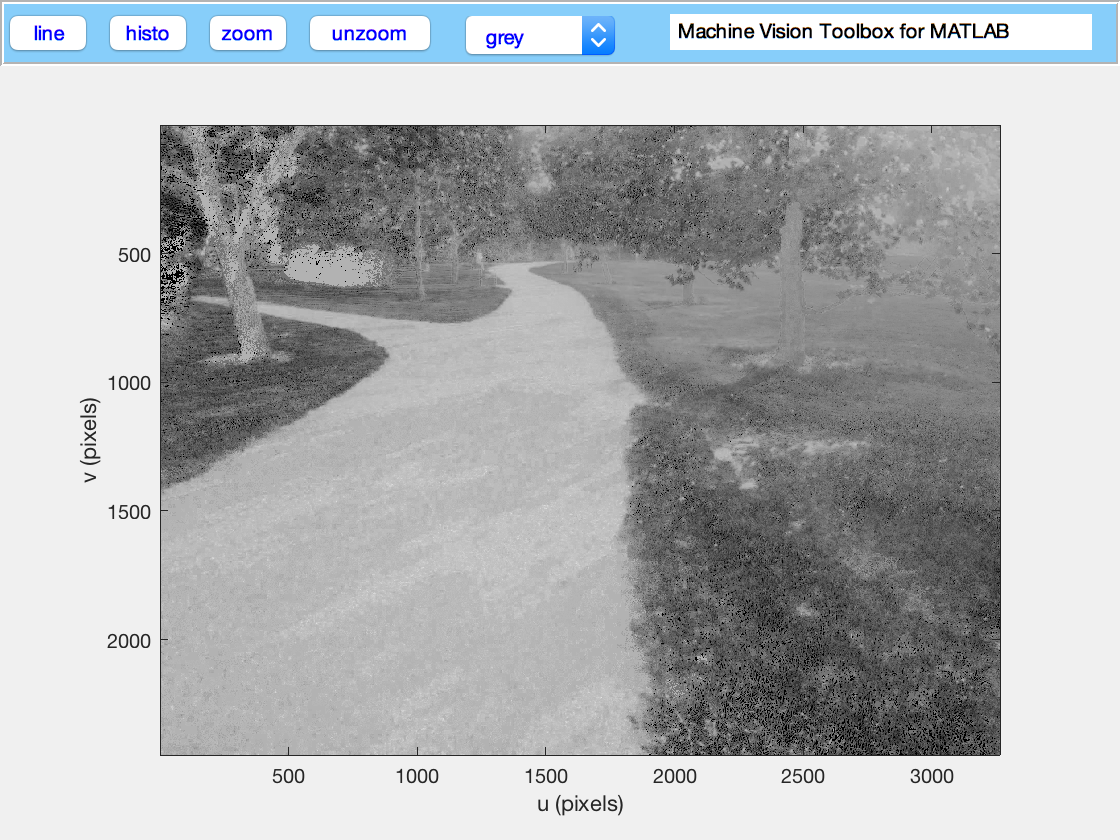

addpath( rvcpath('vision/examples/shadow') )

im = iread('parks.jpg', 'gamma', 'sRGB');
gs = invariant(im, 0.7, 'noexp');
idisp(gs)